% A2.1
% Transfer Function
G = tf([1], [1 11 10]);

% i. Type 0 System; Step Input Error

% Theoretical Calculation
Kp = 1/(1*10);
Ess_theoretical = 1/(1 + Kp);

% Sisotool Confirmation
% Gain = 1
sisotool(G);

[G_closed, T_closed] = feedback(G, 1);
step_response = step(G_closed * 1);
Ess_1 = 1 - step_response(end);

% Gain = 10
sisotool(G, 10);

[G_closed_10, T_closed_10] = feedback(10*G, 1);
step_response_10 = step(G_closed_10 * 1);
Ess_10 = 1 - step_response_10(end);

% Gain = 100
sisotool(G, 100);

[G_closed_100, T_closed_100] = feedback(100*G, 1);
step_response_100 = step(G_closed_100 * 1);
Ess_100 = 1 - step_response_100(end);

% Results
disp('i. Type 0 System; Step Input Error');

i. Type 0 System; Step Input Error


disp(['Theoretical Ess: ' num2str(Ess_theoretical)]);

Theoretical Ess: 0.90909


disp(['Practical Ess (Gain = 1): ' num2str(Ess_1)]);

Practical Ess (Gain = 1): 0.90915


disp(['Practical Ess (Gain = 10): ' num2str(Ess_10)]);

Practical Ess (Gain = 10): 0.50012


disp(['Practical Ess (Gain = 100): ' num2str(Ess_100)]);

Practical Ess (Gain = 100): 0.088169


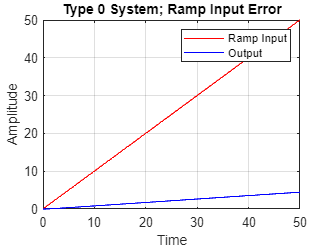

% ii. Type 0 System; Ramp Input Error
H = feedback(G, 1);  % Unity Feedback System

time = 0:0.1:50;
alpha = 1;
ramp = alpha * time;  % Ramp Input

[y, x] = lsim(H, ramp, time);  % Simulate

% Plot the Response
figure;
plot(time, ramp, 'r', time, y, 'b');
legend('Ramp Input', 'Output');
xlabel('Time');
ylabel('Amplitude');
title('Type 0 System; Ramp Input Error');
grid on;


final_value = y(end);
fprintf('Final Value: %.4f\n', final_value);

Final Value: 4.4545


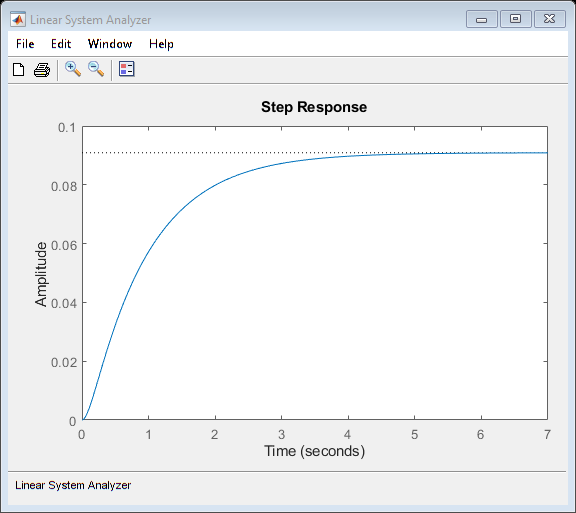


ltiview('step', H);

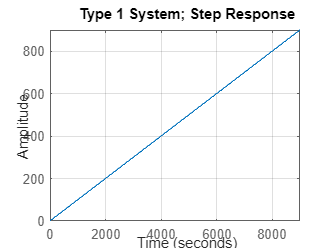

% iii. Type 1 System; Step Input Error

% Type 1 System G2
s = tf('s');
G2 = G/s;

% Sisotool Confirmation
sisotool(G2);

% Analyze Step Response and Steady-State Error
figure;
step(G2);
grid on;
title('Type 1 System; Step Response');

xlabel('Time');
ylabel('Amplitude');

% Steady-State Error
[G2_closed, T2_closed] = feedback(G2, 1);
step_response = step(G2_closed * 1);
Ess_G2 = step_response(end);

fprintf('Steady-State Error for Type 1 System: %.4f\n', Ess_G2);

Steady-State Error for Type 1 System: 0.9985


% iv. Type 1 System; Ramp Error

% Ramp Error
Kv = dcgain(G2);
Ess_ramp_theoretical = 1/Kv;

% Results
disp('iv. Type 1 System; Ramp Error');

iv. Type 1 System; Ramp Error


disp(['Theoretical Ramp Ess: ' num2str(Ess_ramp_theoretical)]);

Theoretical Ramp Ess: 0


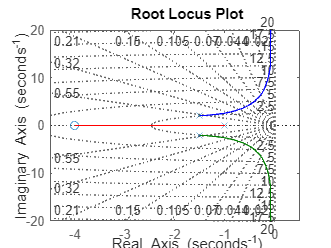

% A2.2

% Define the transfer function
numerator = [1 4];
denominator = conv([1 1], [2 6 13]);
G = tf(numerator, denominator);

% Plot the root locus
figure;
rlocus(G);
title('Root Locus Plot');
grid on;


% Estimate Gain for 1.0s Settling Time
[k, poles] = rlocfind(G, 'st');

% Pole that dominates the Settling Time
dominantPole = poles(end);

% Required Gain
desiredDampingRatio = 0.7;
dampingRatio = abs(imag(dominantPole)) / abs(real(dominantPole));
requiredGain = k / (1 - dampingRatio^2);

fprintf('Estimated gain for 1.0s settling time: %f\n', requiredGain);

Estimated gain for 1.0s settling time: 220.570588
Estimated gain for 1.0s settling time: 226.306513
